Task b:

syms A f0 t pi
xt = A*sin(2*pi*f0*t); 
yt = int(xt,'t',[0,t]) 

$$yt = \frac{A\,{\sin\left(f_{0}\,\pi \,t\right)}^{2}}{f_{0}\,\pi }$$

Task C:

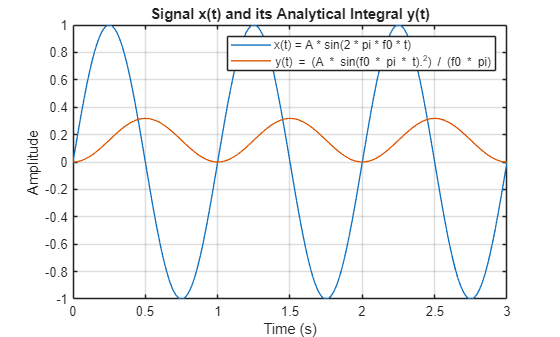

clear;
close all;
clc;
t = 0:0.01:3;  
A = 1;         
f0 = 1;        
xt = A * sin(2 * pi * f0 * t); 
yt = (A * sin(f0 * pi * t).^2) / (f0 * pi); 
figure('Name', 'Task (c): Analytical Plot'); 
plot(t, xt, 'linewidth', 1); 
hold on; 
plot(t, yt, 'linewidth', 1); 
grid on;
title('Signal x(t) and its Analytical Integral y(t)'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) = A * sin(2 * pi * f0 * t)', 'y(t) = (A * sin(f0 * pi * t).^2) / (f0 * pi)'); 

Task D:

a=[1,2,3,4,5];
b= cumsum(a)

b =      1     3     6    10    15


Task E:

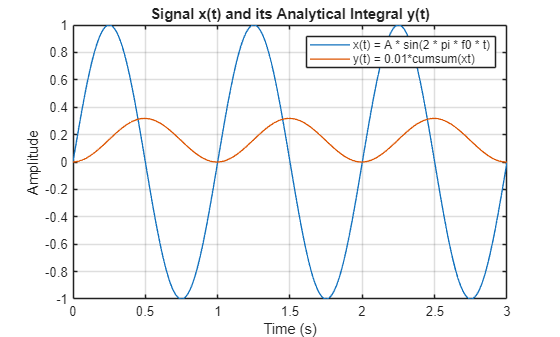

clear;
close all;
clc;
t = 0:0.01:3;  
A = 1;         
f0 = 1;        
xt = A * sin(2 * pi * f0 * t); 
yt = 0.01*cumsum(xt); 
figure('Name', 'Task (c): Analytical Plot'); 
plot(t, xt, 'linewidth', 1); 
hold on; 
plot(t, yt, 'linewidth', 1); 
grid on;
title('Signal x(t) and its Analytical Integral y(t)'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) = A * sin(2 * pi * f0 * t)', 'y(t) = 0.01*cumsum(xt)'); 

Task H:

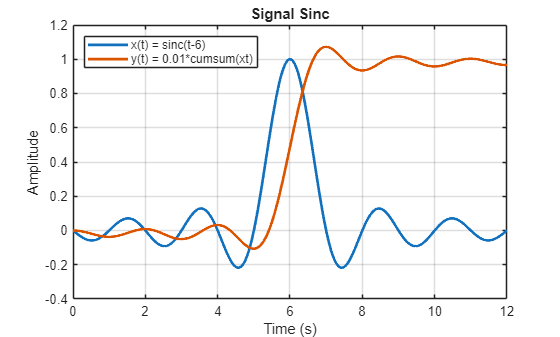

clear; close all; clc;
t = 0:0.01:12;  
xt = sinc(t-6); 
yt = 0.01*cumsum(xt); 
figure('Name', 'Task (H): Sinc'); 
plot(t, xt, 'linewidth', 2); 
hold on; 
plot(t, yt, 'linewidth',2); 
grid on;
xlim([0 12]); 
title('Signal Sinc'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) = sinc(t-6)', 'y(t) = 0.01*cumsum(xt)', 'Location', 'northwest');

Task I:

clear; close all; clc;
a=[1,2,3,4,5]

a =      1     2     3     4     5


b=diff(a)

b =      1     1     1     1


Task K:

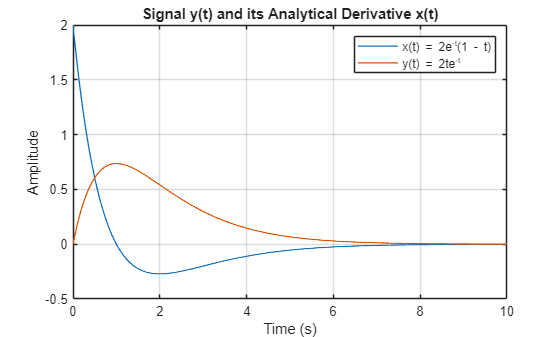

clear;
close all;
clc;
t = 0:0.01:10;         
xt = 2 * exp(-t) .* (1 - t); 
yt = 2 * t .* exp(-t); 
figure('Name', 'Task (K): Numerical Differentiation of a Signal'); 
plot(t, xt, 'linewidth', 1); 
hold on; 
plot(t, yt, 'linewidth', 1); 
grid on;
title('Signal y(t) and its Analytical Derivative x(t)'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) = 2e^{-t}(1 - t)', 'y(t) = 2te^{-t}');

Task L:

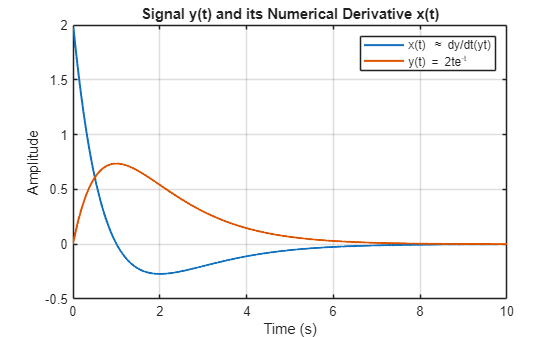

clear;close all;clc;
dt = 0.01;
t = 0:dt:10;          
yt = 2 * t .* exp(-t);
xt = diff(yt) / dt;
xt = [NaN, xt]; 
figure('Name', 'Task (L): Numerical Differentiation'); 
plot(t, xt, 'linewidth', 1.5); 
hold on; 
plot(t, yt, 'linewidth', 1.5); 
grid on;
title('Signal y(t) and its Numerical Derivative x(t)'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) \approx dy/dt(yt)', 'y(t) = 2te^{-t}');

Task M:

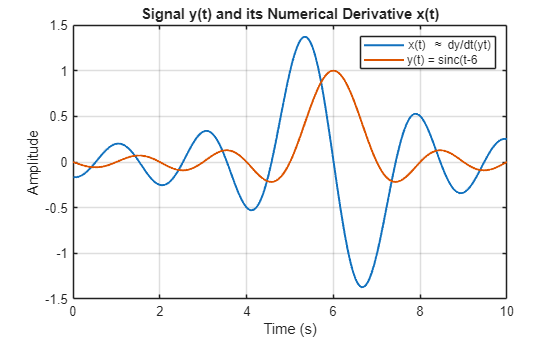

clear;close all;clc;
dt = 0.01;
t = 0:dt:10;          
yt = sinc(t-6);
xt = diff(yt) / dt;
xt = [NaN, xt]; 
figure('Name', 'Task (L): Numerical Differentiation'); 
plot(t, xt, 'linewidth', 1.5); 
hold on; 
plot(t, yt, 'linewidth', 1.5); 
grid on;
title('Signal y(t) and its Numerical Derivative x(t)'); 
xlabel('Time (s)'); 
ylabel('Amplitude'); 
legend('x(t) \approx dy/dt(yt)', 'y(t) = sinc(t-6');